# Test/ Debugger: imgCropMULTI 

**Summary: **Works through step by step the preprocessing and cropping stages. Useful for code debugging and investigating preprocessing quality of a particular frame.

**User notes:**

1) Make sure videos and individual video frames that wished to be investigated are located in the same folder as this live script.

2) Ammend necessary inputs, particularly video/ image file name. Other hyperparameters can also be adjusted as see fit.

V1.0. SWC, 29 Jan 2021.

## 1) Load video

vid_file_name = 'SO5_13umL-7Wat_umL-10kfps x4mag_sh50_C001H001S0026.avi'; %<-------- user-defined input!!
vid = VideoReader(vid_file_name); %read video 
totframes = vid.NumFrames %check total num of frames in video

totframes = 966

## 2) Background generation 

Shows two methods: i) Median and ii) Mode

n = 200;    % number of frames to use for background generation  <-------- user-defined input!!
idx = round(linspace(1,totframes,n)); %vector of index of frame number to be extracted

frameMat = []; 

% for loop to create matrix of frames - for generating background image
for i=1:numel(idx)
    frame = read(vid,idx(i)); 
    frameMat = cat(3,frameMat,frame);
end

tic
med_pix = median(frameMat,3); %compute median of each pixel across all frames in matrix
toc

Elapsed time is 0.309364 seconds.


tic
max_pix = mode(frameMat,3); %compute mode of each pixel across all frames in matrix
toc

Elapsed time is 2.201462 seconds.


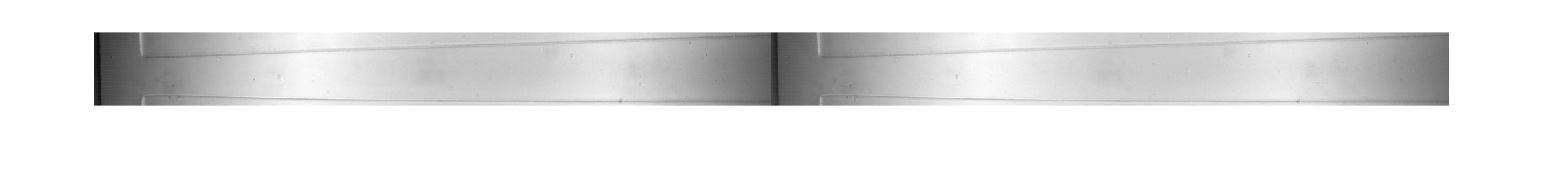

%show generated background 
imshowpair(med_pix, max_pix, 'montage');

## 3) Load image 

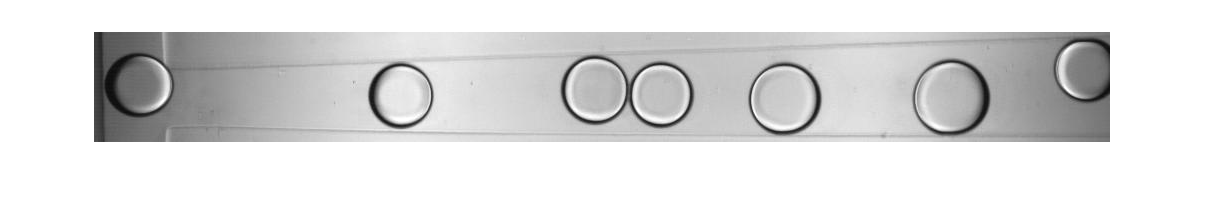

% Load images
I = imread('448.jpg');   %<-------- user-defined input!!

% check images loaded correctly
figure; imshow(I);  

## 4) Image processing

- Background subtraction

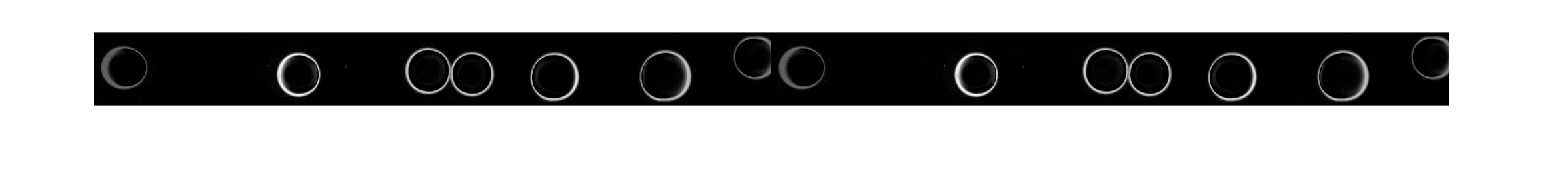

%Median background generation
subMed = med_pix - I; %imshow(subMed); 
%Mode background generation
subMax = max_pix - I; %imshow(subMax)
imshowpair(subMed, subMax, 'montage');

- Binarise image

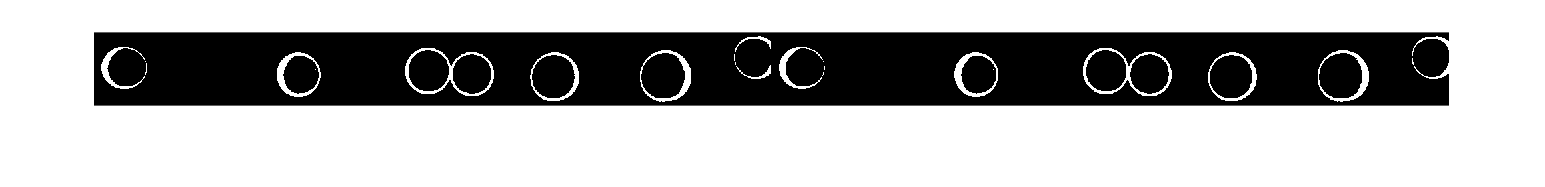

treshold = 0.2; %<-------- user-defined input!!
bin1= imbinarize(subMed, treshold); %imshow(bin1)
bin2= imbinarize(subMax, treshold); %imshow(bin2)

imshowpair(bin1, bin2, 'montage');

- Morphological fill

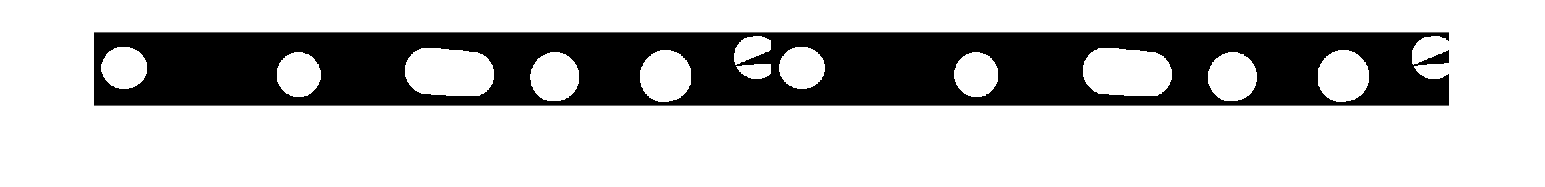

fill1 = bwconvhull(bin1, 'objects'); %imshow(fill1);
fill2 = bwconvhull(bin2, 'objects'); %imshow(fill2);
imshowpair(fill1, fill2, 'montage');

%detect ROI
ROI1 = regionprops('table',fill1) 

ROI1 = 8×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    3446      45.9    53.829     11.5     22.5       69       63
       1       260        51    259.5     50.5        1        1
    3512    307.48    64.073    274.5     30.5       66       67
    8233     533.5     60.77    467.5     23.5      133       73
    4298    691.67    67.407    654.5     30.5       74       73
    4785    857.91    66.329    819.5     27.5       77       77
    1570    986.67    24.954    960.5      6.5       56       43
     925    992.98    58.316    963.5     47.5       53       23


ROI2 = regionprops('table',fill2) 

ROI2 = 8×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    3452    45.868    53.804     11.5     22.5       69       63
       1       260        51    259.5     50.5        1        1
    3512    307.48    64.073    274.5     30.5       66       67
    8233     533.5     60.77    467.5     23.5      133       73
    4300    691.66     67.41    654.5     30.5       74       73
    4785    857.89    66.325    819.5     27.5       77       77
    1572     986.7    24.936    960.5      6.5       56       43
     955     993.1    58.055    963.5     46.5       53       24


- Noise objects removal

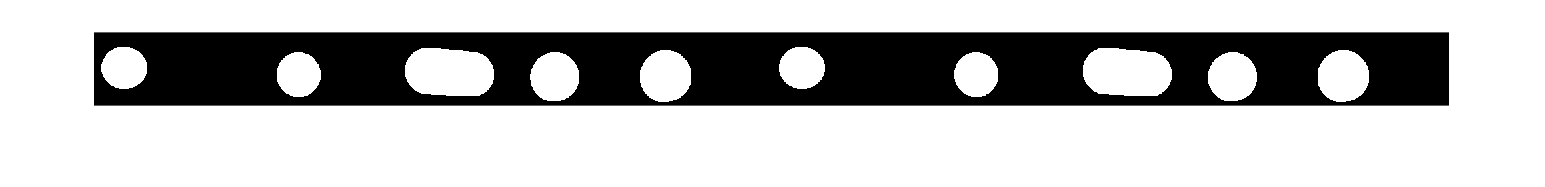

cfill1 = bwareaopen(fill1,1800);
cfill2 = bwareaopen(fill2,1800);
figure; imshowpair(cfill1, cfill2, 'montage')


% detect ROI
cROI1 = regionprops('table',cfill1) %ROI1 = struct2table(ROI1)

cROI1 = 5×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    3446      45.9    53.829     11.5     22.5       69       63
    3512    307.48    64.073    274.5     30.5       66       67
    8233     533.5     60.77    467.5     23.5      133       73
    4298    691.67    67.407    654.5     30.5       74       73
    4785    857.91    66.329    819.5     27.5       77       77



cROI2 = regionprops('table', cfill2) %ROI2 = struct2table(ROI2)

cROI2 = 5×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    3452    45.868    53.804     11.5     22.5       69       63
    3512    307.48    64.073    274.5     30.5       66       67
    8233     533.5     60.77    467.5     23.5      133       73
    4300    691.66     67.41    654.5     30.5       74       73
    4785    857.89    66.325    819.5     27.5       77       77


- Remove drops outside of main flow channel

delCriteria = 140; % remove drop if centroid position < delCritera  <-------- user-defined input!!

cROI1(cROI1.Centroid(:,1) < delCriteria, :) = []

cROI1 = 4×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    3512    307.48    64.073    274.5     30.5       66       67
    8233     533.5     60.77    467.5     23.5      133       73
    4298    691.67    67.407    654.5     30.5       74       73
    4785    857.91    66.329    819.5     27.5       77       77


cROI2(cROI2.Centroid(:,1) < delCriteria, :) = []

cROI2 = 4×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    3512    307.48    64.073    274.5     30.5       66       67
    8233     533.5     60.77    467.5     23.5      133       73
    4300    691.66     67.41    654.5     30.5       74       73
    4785    857.89    66.325    819.5     27.5       77       77


## 5) Plot results

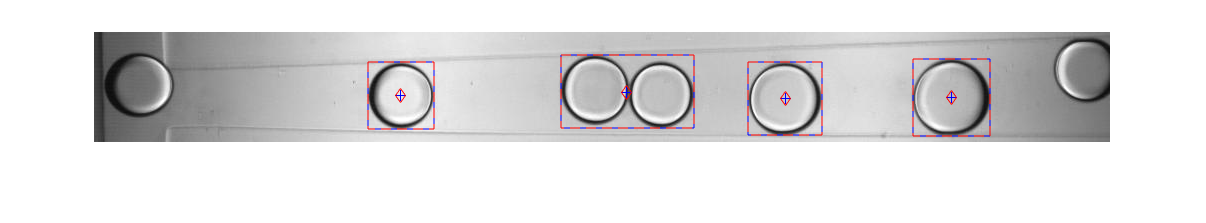

figure; imshow(I);
hold on

% from ROI1 data
plot(cROI1.Centroid(:,1), cROI1.Centroid(:,2), 'b+')

for i=1:height(cROI1)
    rectangle('Position',cROI1.BoundingBox(i,:),'EdgeColor','b')
end
% from ROI2 data
plot(cROI2.Centroid(:,1), cROI2.Centroid(:,2), 'rd')

for i=1:height(cROI2)
    rectangle('Position',cROI2.BoundingBox(i,:),'EdgeColor','r','LineStyle', '--')
end

## 6) Crop and show individual drops 

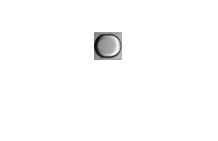

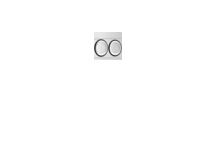

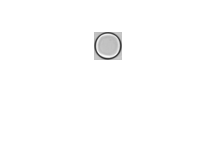

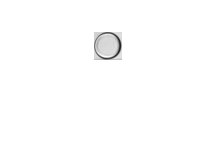

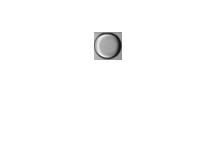

 
roiTable = cROI1.BoundingBox; 
cropSize = [28 28];

for i = 1: height(roiTable)
    dim = max([roiTable(i,3:4)]); % this will be the 
    % x-coord of centroid of cropping region
    cx = roiTable(i,1) + roiTable(i,3)/2; 
    % y-coord of centroid of cropping region
    cy = roiTable(i,2) + roiTable(i,4)/2; 
    
    % coordinates of bottom-left vertex of intended crop region 
    xmin = cx - dim/2;
    ymin = cy - dim/2; 
    
    % crop region defined as [x-coord of bottom left point, y-coord of
    % bottom left point, width, height]
    Img = imcrop(I, [xmin, ymin, dim, dim]);
    
    % resize cropped image
    Img = imresize(Img, cropSize);
    
    %show image
    figure; imshow(Img)
end 